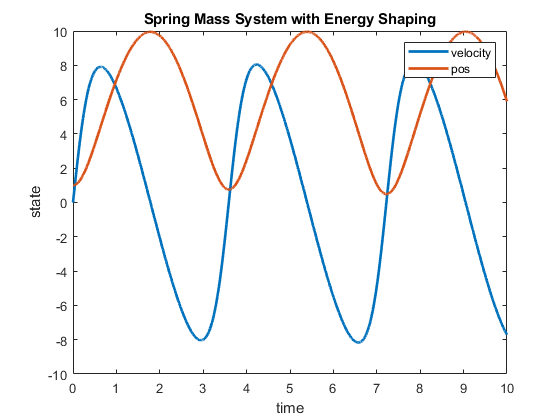

clc
clear
close all

tfinal = 10; dt = 0.001; % simulation parameters
k = 1;
m = 1;
b = 0.1;
A_sys = [0 1;-k/m 0]; B_sys = [0; 1/m]; 
A_PHS = [0 -1/m;k 0]; B_PHS = [1; 0];
x_des = 10; lambda = -1;

x0 = [1;0]; x = x0; t = 0; H_sys = 0; % initial condition
p0 = m*x(2); p = p0; vsquare0 = (p0/m)^2; vsquare = vsquare0;
xm0 = x(1); xm = xm0;
phs0 = [p0;xm0]; phs = phs0;

Em0 = p0^2/(2*m); Em=Em0;
Ek0 = k*xm0^2/2; Ek =Ek0; 
Er = 0;

X = []; PHS = []; T = []; % initialize memory
EM = []; EK = []; Vsquare = [];
while (t <= tfinal)
    T = [T,t]; X = [X,x]; PHS = [PHS,phs];
    EM = [EM,Em]; EK = [EK,Ek]; Vsquare = [Vsquare, vsquare];

    H_sys = p^2/(2*m) + (k*xm^2)/2;
    Em = p^2/(2*m); Ek = (k*xm^2)/2; Er = Er + (phs(1)/m)^2*dt;
    E_error = H_sys - k*x_des^2/2;
    u = 0.5*lambda*(E_error);
    phs = phs + dt*((A_PHS*phs + B_PHS*u));
    p = phs(1)/m; xm = phs(2)/k;
    t = t + dt; % time increment
    
end
ER = b*Er;


figure(1)
plot(T,PHS,LineWidth=2);
ylabel('state')
xlabel('time')
legend('velocity','pos')
title('Spring Mass System with Energy Shaping')

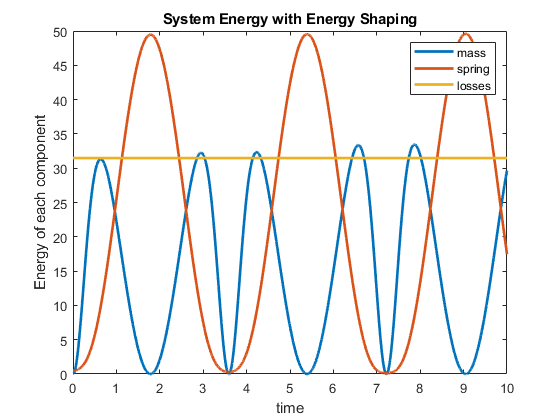

figure(2)
plot(T,EM,LineWidth=2); hold on;
plot(T,EK,LineWidth=2); hold on;
plot(T,ER.*ones(size(EM)),LineWidth=2);
ylabel('Energy of each component')
xlabel('time')
legend('mass','spring','losses')
title('System Energy with Energy Shaping')
hold off

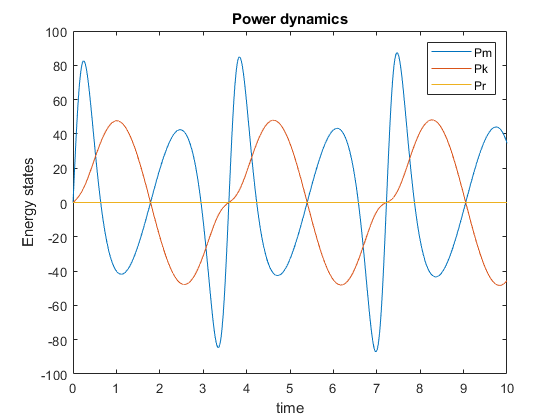

PM = diff(EM)./diff(T);
PK = diff(EK)./diff(T);
PR = b*diff(Vsquare)./diff(T);

figure(3)
plot(T(2:end),PM); hold on;
plot(T(2:end),PK); hold on;
plot(T(2:end),PR);
ylabel('Energy states')
xlabel('time')
legend('Pm','Pk','Pr')
title('Power dynamics')
hold off

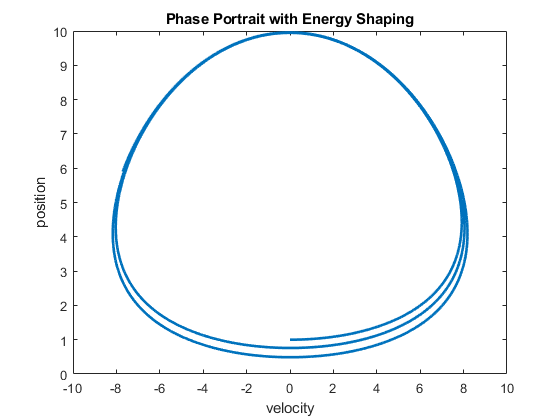

figure(4)
plot(PHS(1,:),PHS(2,:),LineWidth=2);
ylabel('position')
xlabel('velocity')
title('Phase Portrait with Energy Shaping')